# Wound Healing: Sample Image Processing Pipeline

This script contains a sample image processing pipeline for the wound healing project.

**Author: **Joshua Pickard (jpic@umich.edu)

**Date: **jpic@umich.edu

## Overview of Image Processing Pipeline

Each channel of the image is processed independently. In this section, the input, intermediate results, and final stages of the pipeline are shown for the red, green, and oblique steps of the pipeline.

### Red Channel

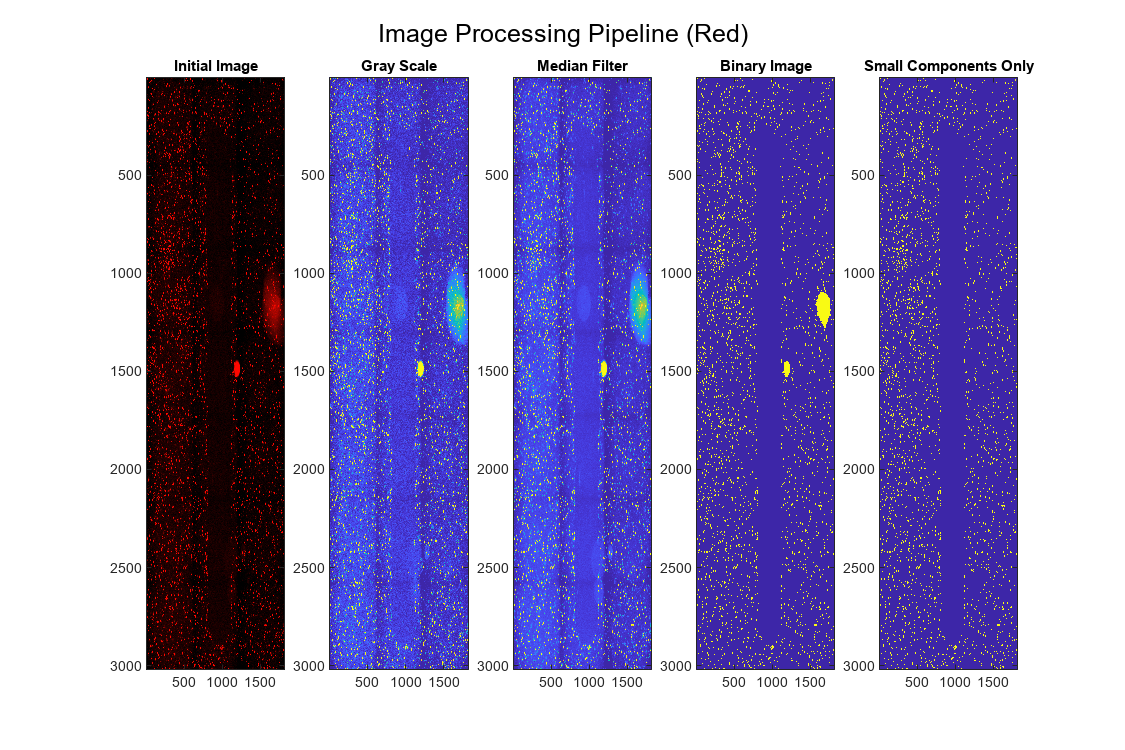

figure('Position', [10 10 900 600]); sgtitle('Image Processing Pipeline (Red)')
c = 5; % Number of columns in figure / steps in process

% Read in the image
img = imread('2023-03-28-BJPF-s06-Stitched_t001c1.tif');
subplot(1,c,1); imagesc(img); title('Initial Image');

% Convert the image to grayscale
gray_img = rgb2gray(img);
subplot(1,c,2); imagesc(gray_img); title('Gray Scale');

% Apply median filter to smooth the image
gray_img = medfilt2(gray_img, [4 4]);
subplot(1,c,3); imagesc(gray_img); title('Median Filter');

% Threshold the image
threshold = graythresh(gray_img);
bw_img = imbinarize(gray_img,threshold);
subplot(1,c,4); imagesc(bw_img); title('Binary Image');

% Remove large connected components using bwareafilt
filtered_img = bwareafilt(bw_img, [0, 500]);
subplot(1,c,5); imagesc(filtered_img); title('Small Components Only');

After the pipeline is complete, island detection is performed to find the individual cells, and boxes are drawns around the cells in the final output.

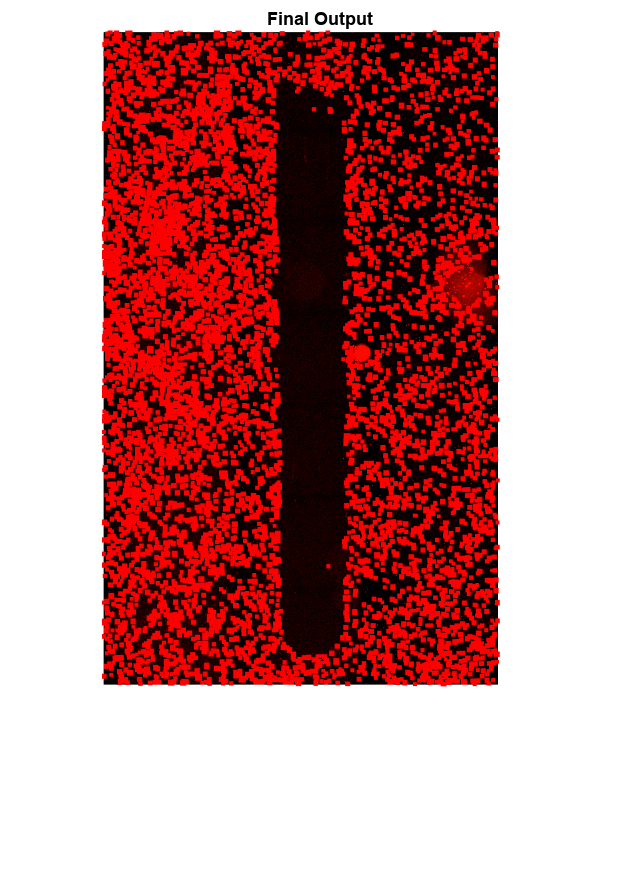

% Label the image and get the region properties
labeled_img = bwlabel(filtered_img);
props = regionprops(labeled_img,'Area','BoundingBox','Centroid');

% Create a figure to display the segmented cells
figure; hold on; title('Final Output')
imshow(img);

% Loop through the regions and plot them on the image
for i = 1:length(props)
    bbox = props(i).BoundingBox;
    x = bbox(1);
    y = bbox(2);
    w = bbox(3);
    h = bbox(4);
    rectangle('Position',[x,y,w,h],'EdgeColor','r','LineWidth',2);
end

### **Green Channel**

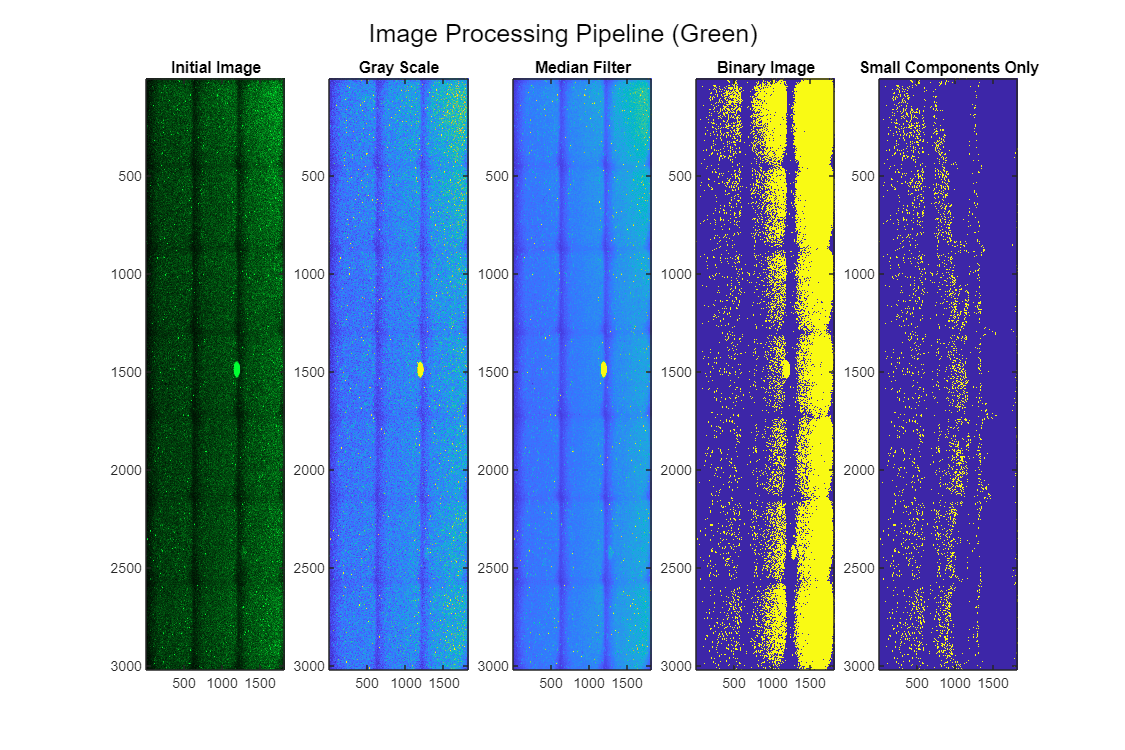

figure('Position', [10 10 900 600]); sgtitle('Image Processing Pipeline (Green)')
c = 5; % Number of columns in figure / steps in process

% Read in the image
img = imread('2023-03-28-BJPF-s06-Stitched_t001c3.tif');
subplot(1,c,1); imagesc(img); title('Initial Image');

% Convert the image to grayscale
gray_img = rgb2gray(img);
subplot(1,c,2); imagesc(gray_img); title('Gray Scale');

% Apply median filter to smooth the image
gray_img = medfilt2(gray_img, [4 4]);
subplot(1,c,3); imagesc(gray_img); title('Median Filter');

% Threshold the image
threshold = graythresh(gray_img);
bw_img = imbinarize(gray_img,threshold);
subplot(1,c,4); imagesc(bw_img); title('Binary Image');

% Remove large connected components using bwareafilt
filtered_img = bwareafilt(bw_img, [0, 500]);
subplot(1,c,5); imagesc(filtered_img); title('Small Components Only');